%Fourier Series in Interval -pi,pi
syms t; %Define t
k=(0:50)'; %Let's consider an interval k
f=t/2; %Let's consider the function t/2

% Compute the Fourier coefficients
a = zeros(size(k));
b = zeros(size(k));
g = zeros(size(k));

for idx = 1:length(k)
    current_k = k(idx);
    a(idx) = 1/pi * int(f * cos(current_k * t), t, -pi, pi);
    b(idx) = 1/pi * int(f * sin(current_k * t), t, -pi, pi);
    g(idx) = 1/(2*pi) * int(f * exp(-1i * current_k * t), t, -pi, pi);
end


%Approx with ak and bk
Fapprox = 0;
for idx = 1:length(k)
    Fapprox = Fapprox + a_numeric(idx) * cos(k(idx) * t) + b_numeric(idx) * sin(k(idx) * t);
end

Unrecognized function or variable 'a_numeric'.


%Approx with gamma
W = exp(1i * k * t); % Create the matrix for exp(1i*k*t)
Fapprox2 = sum(g' * W); % Compute the approximation

%disp(Fapprox');
%disp(Fapprox2');

clf; hold on;
fplot(f,[-pi-1,pi+1],'Color','green')
fplot(Fapprox,[-pi-1,pi+1],'Color','blue');
hold off;

clf; hold on;
fplot(f,[-pi,pi],'Color','green')
fplot(real(Fapprox2),[-pi,pi],'Color','blue'); %Display real
hold off;


%---------------------
f=t/2;
ak = zeros(size(k));
bk = zeros(size(k));

for idx = 1:length(k)
    current_k = k(idx);
    ak(idx) = 1/pi * int(f * cos(current_k * t), t, -pi, pi);
    bk(idx) = 1/pi * int(f * sin(current_k * t), t, -pi, pi);
end

a_numeric=double(ak); b_numeric=double(bk);

Fapprox2 = 0;
for idx = 1:length(k)
    Fapprox2 = Fapprox + a_numeric(idx) * cos(k(idx) * t) + b_numeric(idx) * sin(k(idx) * t);
end


%Apply the shift
tau=pi; %shift by tau

%Formulas for shifting
a_shifted = a_numeric.*cos(k*tau) + b_numeric.*sin(k*tau);
b_shifted = b_numeric.*cos(k*tau) - a_numeric.*sin(k*tau);

Fapprox_shifted=0;
for idx=1:length(k)
    Fapprox_shifted = Fapprox_shifted + a_shifted(idx)*cos(k(idx) * t) + b_shifted*sin(k(idx)*t);
end

clf; hold on;
fplot(f,[0,2*pi],'Color','green')
fplot(Fapprox_shifted,[0,2*pi],'Color','blue');
hold off;


%-------------------------------------

% Now consider the interval +T/2 -T/2
f=t/2;
k=(0:100)';
b=1; a=0; T=(b-a);
ak = zeros(size(k));
bk = zeros(size(k));
gk = zeros(size(k));

for idx = 1:length(k)
    current_k = k(idx);
    ak(idx) = 2/T * int(f * cos((2*pi*current_k)/T *t), t, -T/2, T/2);
    bk(idx) = 2/T * int(f * sin((2*pi*current_k)/T *t), t, -T/2, T/2);
    gk(idx) = 1/T * int(f * exp(-1i * current_k *2*pi/T*t), t, -T/2, T/2);
end

a_numeric=double(ak); b_numeric=double(bk); g_numeric=double(gk);
Fapprox=0;

for idx = 1:length(k)
    current_k = k(idx);
    Fapprox = Fapprox + a_numeric(idx) * cos((2*pi*current_k)/T *t) + b_numeric(idx) * sin((2*pi*current_k)/T *t);

end

clf; hold on;
fplot(f,[-T,T],'Color','green')
fplot(Fapprox,[-T,T],'Color','blue');
hold off;

Fapprox_g=0;
for idx=1:length(k)
    Fapprox_g = Fapprox_g + g_numeric(idx)* exp(1i * current_k * (2*pi)/T * t);
end

clf; hold on;
fplot(f,[-T,T],'Color','green')
fplot(imag(Fapprox_g),[-T,T],'Color','blue');
hold off;

t=linspace(-2*pi,2*pi,1000);
T = 2*pi;
k=(0:100)';
F1=rectpuls(t,2*pi);

clf; hold on;
plot(F1);
hold off;

FR1=fft(F1) / length(F1);
FR1=fftshift(FR1);
ak1 = real(FR1); bk1= imag(FR1);

F1approx=0;
N = length(t); 
mid_idx = floor(N/2) + 1; 
for idx=1:length(k)
    current_k = k(idx);
    F1approx = F1approx +ak1(mid_idx+current_k)*cos((2*pi*k(idx))/T*t)+bk1(mid_idx+current_k)*sin((2*pi*k(idx))/T*t);
end

clf; hold on;
    plot(F1approx);
hold off;

F2=tripuls(t,2*pi);
clf; hold on;
plot(F2);
hold off;

FR2=fft(F2)/length(F2);
FR2=fftshift(FR2);
ak2=real(FR2); bk2=imag(FR2);

F2approx=0;
for idx=1:length(k)
    current_k = k(idx);
    F2approx = F2approx +ak2(mid_idx+current_k)*cos((2*pi*k(idx))/T*t)+bk2(mid_idx+current_k)*sin((2*pi*k(idx))/T*t);
end

clf; hold on;
    plot(F2approx);
hold off;

%Hadamard Product 
F1F2 = F1.*F2;
clf; hold on;
    plot(F1,'Color','blue');
    plot(F2,'Color','red','LineWidth',4);
    plot(F1F2,'Color','green','LineWidth',2,'LineStyle','--');
hold off;


fun = @abs;  % Function to be analyzed
fun1 = @sign; % Derivative of the function

T = 2*pi; % Period of the function
N = 50;   % Number of terms in Fourier series

% Define the frequency components
k = (-N/2:N/2)'; 

% Compute the Fourier series coefficients 'c' for the function 'fun'
% Note: We need to normalize the function over the interval [-pi, pi]
% and the coefficients are calculated using numerical integration

% Fourier coefficients computation
c = zeros(length(k), 1); % Initialize coefficients
for idx = 1:length(k)
    c(idx) = (1/T) * integral(@(x) fun(x) .* exp(-1i * k(idx) * x), -pi, pi);
end

% Coefficients of the differentiated series
c1 = 1i * k .* c; 

% Define the variable 'x' over which the partial sum is computed
x = linspace(-pi, pi, 1000); % Define x in the interval [-pi, pi]

% Compute the partial sum of the Fourier series
S1 = zeros(size(x)); % Initialize partial sum
for idx = 1:length(k)
    S1 = S1 + c1(idx) * exp(1i * k(idx) * x);
end

% Plot the result
hold on;
plot(x, real(S1));
fplot(fun);
fplot(fun1);
hold off;

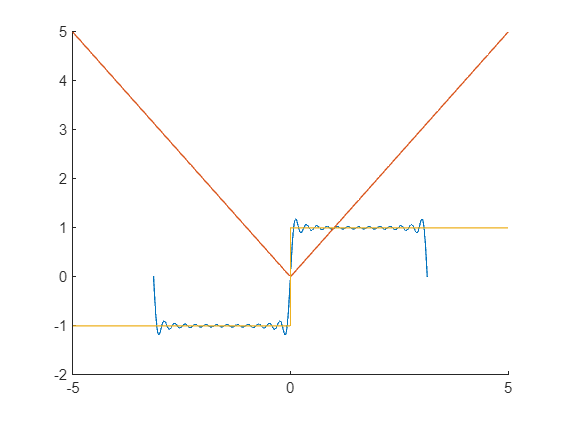

f = @sign;

T=2*pi; N=50;
k=(-N/2:N/2)';
x = linspace(-T/2, T/2, 1000); % Define x in the interval [-pi, pi]

gamma=zeros(length(k),1);
for idx= 1:length(k)
    c(idx) = 1/T * integral(@(x) f(x).* exp(-1i*k(idx)*x),-T/2,T/2);
end

S1=zeros(size(x));
for idx=1:length(k)
    S1=S1+c1(idx)*exp(1i*k(idx)*x);
end

clf; hold on;
plot(x, real(S1));
fplot(fun);
fplot(fun1);
hold off;